% Copyright <2022> <Haodong Jiang, Wentao Wang, Yuan Shen, Xinghan Li, Xiaoqiang Ren, Biqiang Mu, Junfeng Wu>
% Haodong Jiang, SLAMLab-CUHKSZ, September 2022
% haodongjiang@link.cuhk.edu.cn, https://github.com/SLAMLab-CUHKSZ 
% paper link: https://arxiv.org/abs/2209.06779

# Calibrate bias ,slope and sigma

clear;
close all;
clc;
format long
%The trolley is still at the end of each dataset, and we use thsee measurements to calculate the sample variance.
aaa=[100,200,320];

## 1. Anchor position

A=[-3.4203,0.0016,3.6056,3.6011,3.5674,-0.0072,-3.4673,-3.4858;
    3.0053,3.0110,2.9795,-0.0008,-3.0087,-2.9652,-2.9587,-0.0098;
    1.0442,1.0446,1.0463,1.0422,1.0443,1.0444,1.0445,1.0447];

## 2. Loading data

path={'../../Planar_Dataset/Dynamic/calibration_dataset/'};
UWBfile={'UWB_cali_tag0','UWB_cali_tag1','UWB_cali_tag2'};
OPTfile={'motion_capture_cali_tag0','motion_capture_cali_tag1','motion_capture_cali_tag2'};
bias=zeros(24,1);
slope=zeros(24,1);
sigma=zeros(24,1);

for u=1:length(UWBfile)
    UWBfile_name=strcat(path+string(UWBfile(u)),'.csv');
    OPTfile_name=strcat(path+string(OPTfile(u)),'.csv');

    UWB=readtable(UWBfile_name);
    UWBdata=readmatrix(UWBfile_name);
    UWBdata(:,1)=datenum(UWB{:,1});
    OPT=readtable(OPTfile_name);
    OPTdata=readmatrix(OPTfile_name);
    OPTdata(1,:)=[];
    OPTdata(:,1)=datenum(OPT{:,1});

## 3. Data cleaning   

###     Eliminate NaN

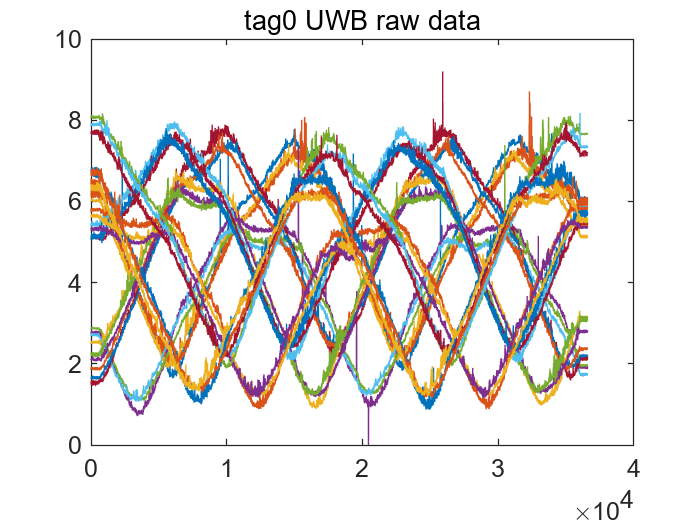

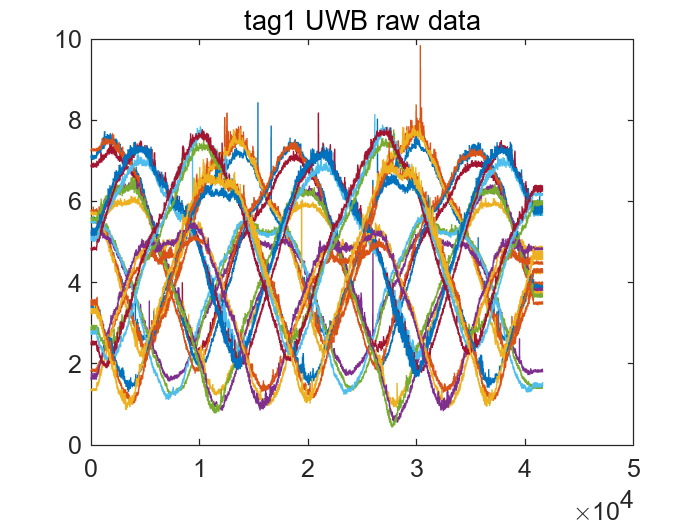

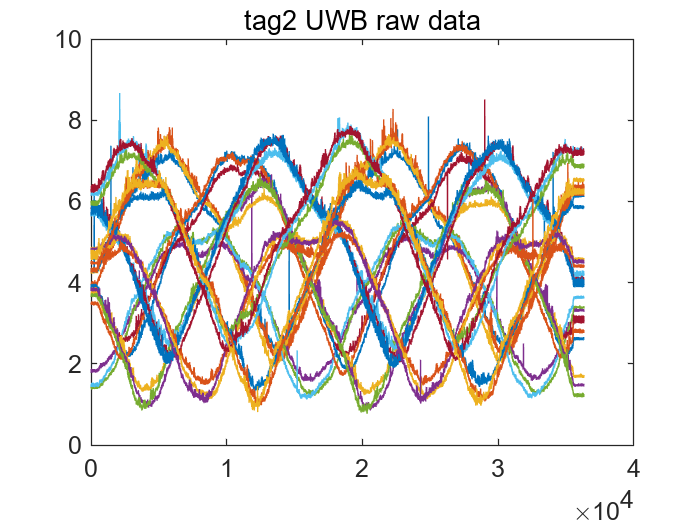

    [uwb_nan,~]=find(isnan(UWBdata));
    uwb_nan=unique(uwb_nan);
    UWBdata(uwb_nan,:)=[];

    figure
    set(gca,'Fontname', 'Times New Roman')
    plot(UWBdata(:,2:end))
    title(['tag',num2str(u-1),' UWB raw data'])
    saveas(gcf,strcat('.\Image\tag'+string(u-1)+'_UWB_raw_data.png'));

###     Eliminate abnomal data and interpolate

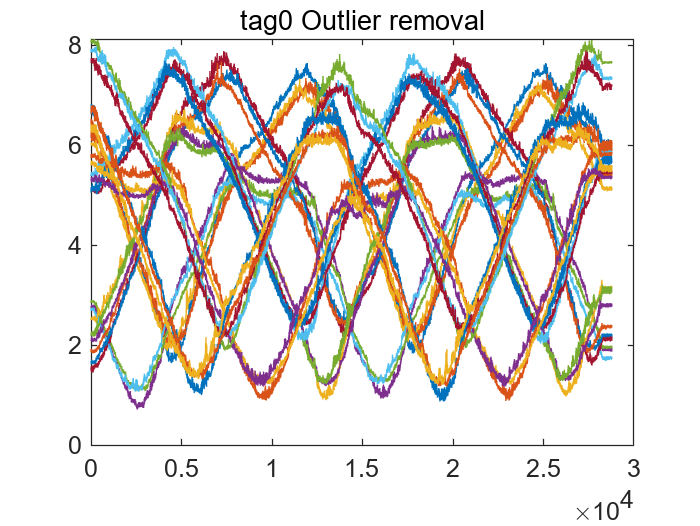

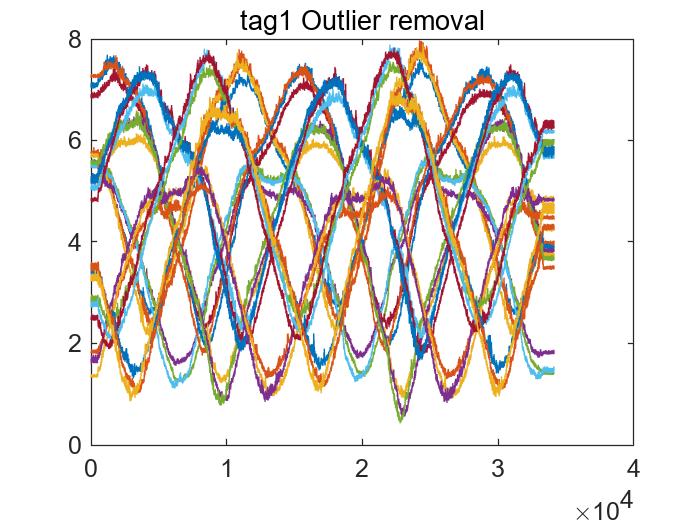

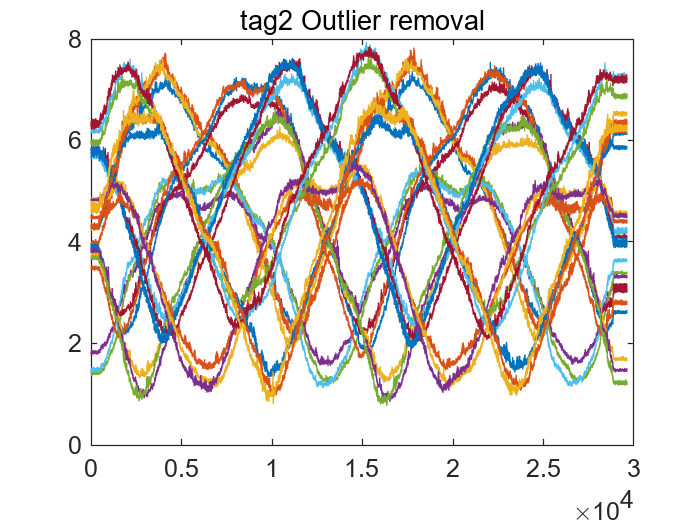

    %%eliminate the extremely abnormal data
    abnormal_threshold=0.3;
    for l=1:30
        outlier_index=[];
        for i=2:length(UWBdata)
            if max(abs(UWBdata(i,:)-UWBdata(i-1,:)))>abnormal_threshold
                outlier_index=[outlier_index,i];
            end
        end
        UWBdata(outlier_index,:)=[];
    end

    %%out_lier rejection
    time_window=10;
    outlier_threshold=0.1;
    outlier_index=[];
    v_max=1;
    for i=3:length(UWBdata)
        if i<=time_window
            min_data=min(UWBdata(1:i-1,:));
            if max(UWBdata(i,:)-min_data)>outlier_threshold+v_max*(i-1)/100
                outlier_index=[outlier_index,i];
            end
        else
            min_data=min(UWBdata(i-time_window:i-1,:));
            if max(UWBdata(i,:)-min_data)>outlier_threshold+v_max*time_window/100
                outlier_index=[outlier_index,i];
            end
        end
    end
    UWBdata(outlier_index,:)=[];

    figure
    set(gca,'Fontname', 'Times New Roman')
    plot(UWBdata(:,2:end))
    title(['tag',num2str(u-1),' Outlier removal'])
    saveas(gcf,strcat('.\Image\tag'+string(u-1)+'_UWB_Outlier_removal.png'));

###     Measurement alignment

    opt_data=zeros(length(UWBdata),3);
    for t = 1:length(UWBdata)
        time=OPTdata(:,1)-UWBdata(t,1);  %assume that the opt measurment starts earlier
        instinct=find(time>0);
        if isempty(instinct)
            break
        else
            front=instinct(1)-1;
            back=instinct(1);
            alpha=abs(time(front))/(abs(time(front))+time(back));
            opt_data(t,:)=OPTdata(front,2:4)*alpha+OPTdata(back,2:4)*(1-alpha);%interpolation
        end
    end
    uwb_data=UWBdata;
    uwb_data(:,1)=[];%% eliminate the first column, which is time

    opt_zero=find(all(opt_data==0,2));
    opt_data(opt_zero,:)=[];
    uwb_data(opt_zero,:)=[];

    uwb_data=uwb_data(:,[1,4,7,10,13,16,19,22,2,5,8,11,14,17,20,23,3,6,9,12,15,18,21,24]);  %switch the data order

## 4. Calibrate  for differernt tag-anchor

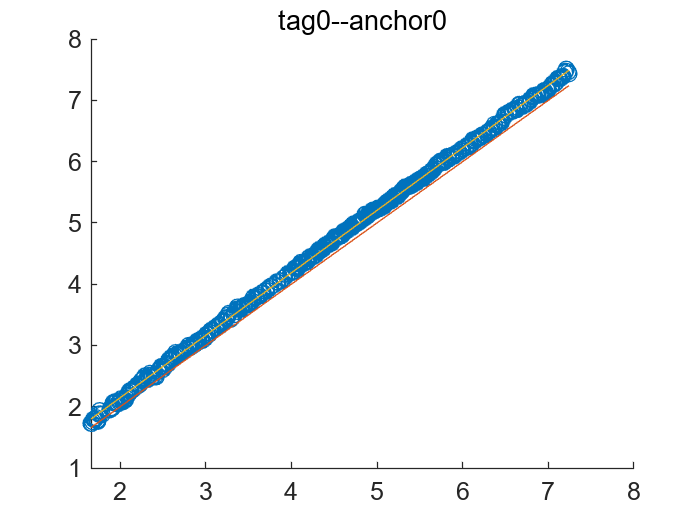

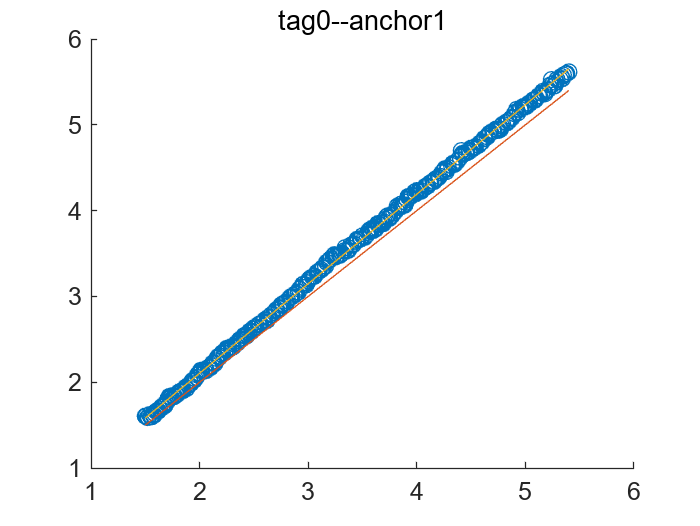

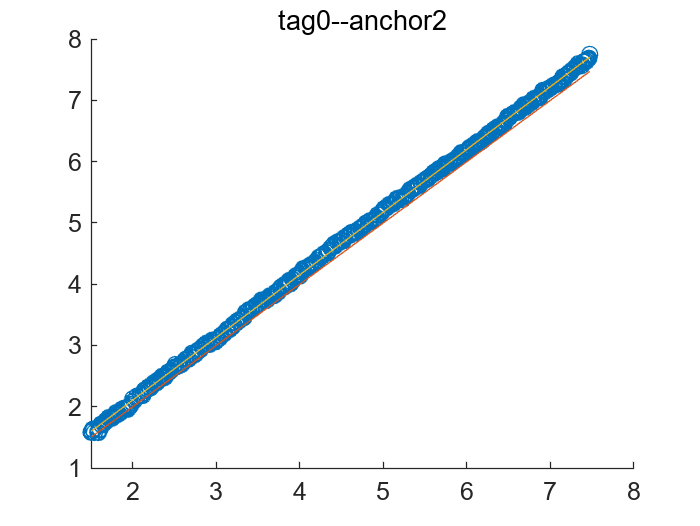

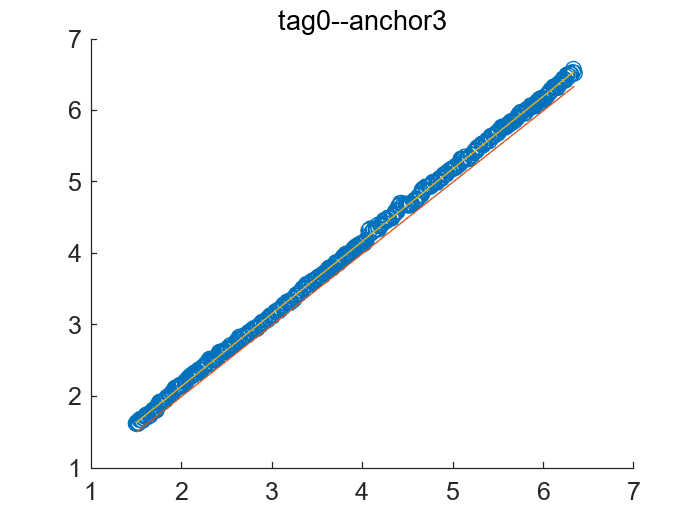

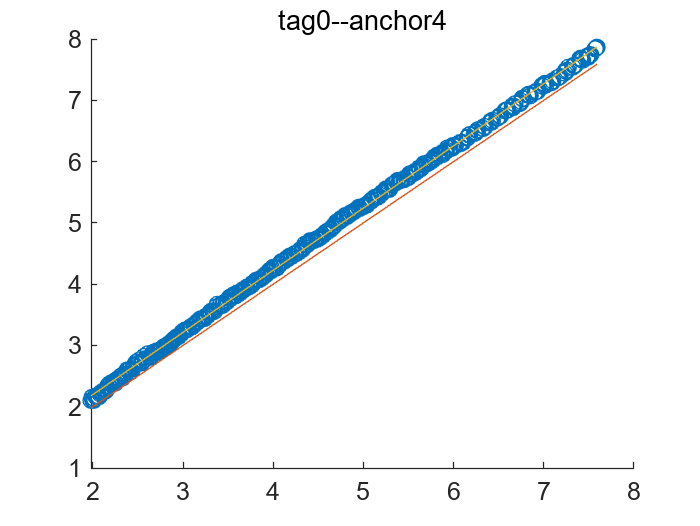

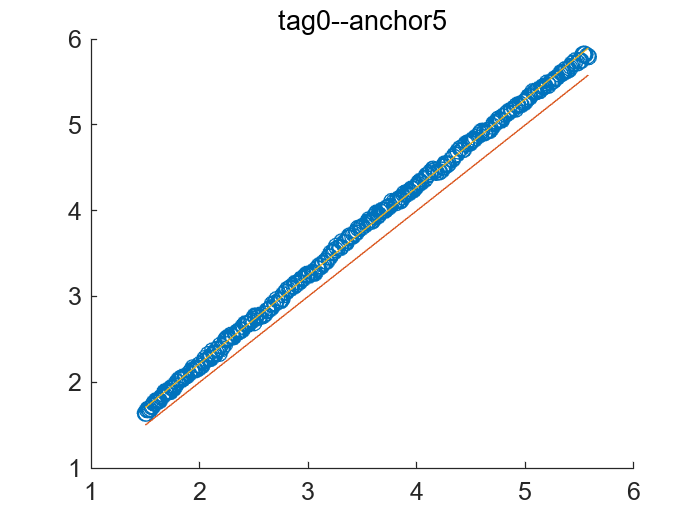

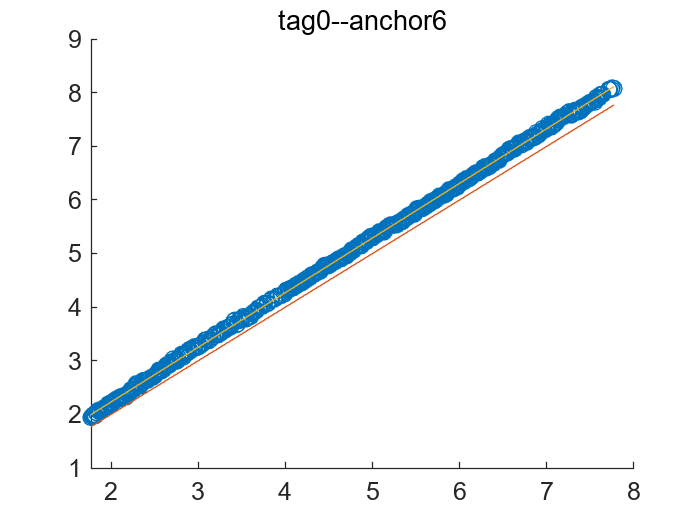

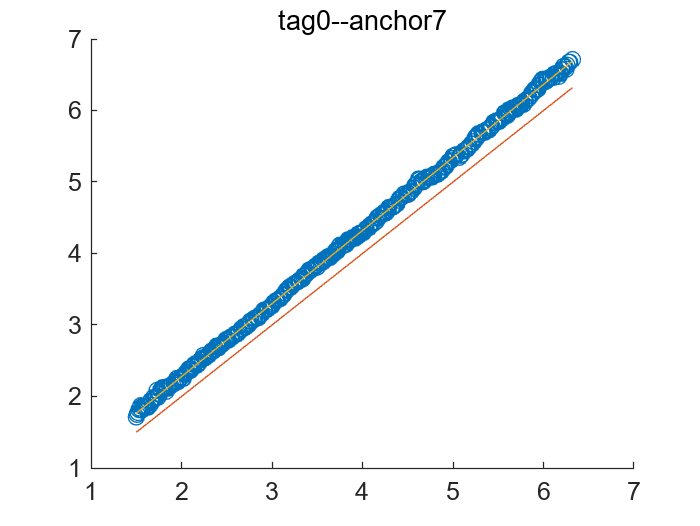

    uwb_data1=uwb_data(end-aaa(u):end,:);
    uwb_data1=uwb_data1(:,8*(u-1)+1:8*u);
    sigma(8*(u-1)+1:8*u,:)=std(uwb_data1);
    
    uwb_data2=uwb_data(:,8*(u-1)+1:8*u);
    data_number=length(opt_data);
    data_amount_low_threshold=15;
    data_amount_up_threshold=2000;
    for m=1:8  %anchor index
        am=A(:,m); %ancor_m position
        uwb_measurement=uwb_data2(:,m);
        pd=opt_data-repmat(am',data_number,1);
        true_distance=zeros(data_number,1);
        for i=1:data_number
            true_distance(i)=roundn(norm(pd(i,:)),-2);  %cm accuracy
        end

        min_distance=min(true_distance);
        if min_distance <=1.5
            min_distance =1.5;
        end
        max_distance=max(true_distance);

        k=(max_distance-min_distance)/0.01+1;
        k=round(k);
        truth=min_distance:0.01:max_distance;
        measurement_bar=zeros(k,1);

        for i=1:k
            index=find(true_distance==min_distance+0.01*(i-1));
            if length(index)<=data_amount_low_threshold
            elseif length(index)>=data_amount_up_threshold
            else
                measurement_bar(i)=mean(uwb_measurement(index));
            end
        end

        zero=find(measurement_bar==0);
        measurement_bar(zero)=[];
        truth(zero)=[];
        ind_nan = find(isnan(measurement_bar));
        measurement_bar(ind_nan)=[];
        truth(ind_nan)=[];

        error=measurement_bar-truth';
        p=polyfit(truth',error,1);
        bias(m+(u-1)*8)=p(2);
        if (p(1)<0)
            slope(m+(u-1)*8)=0;
        else
            slope(m+(u-1)*8)=p(1);
        end
        
        figure
        set(gca,'Fontname','Times New Roman')
        scatter(truth,measurement_bar)
        hold on
        plot(truth,truth)
        plot(truth,(p(1)+1)*truth+p(2));
        hold off
        title(['tag',num2str(u-1),'--anchor',num2str(m-1)])
        saveas(gcf,strcat('.\Image\tag'+string(u-1)+'_anchor'+string(m-1)+'.png'));
    end

end
writematrix(sigma,'.\sigma.xlsx');
writematrix(bias,'.\bias.xlsx');
writematrix(slope,'.\slope.xlsx');